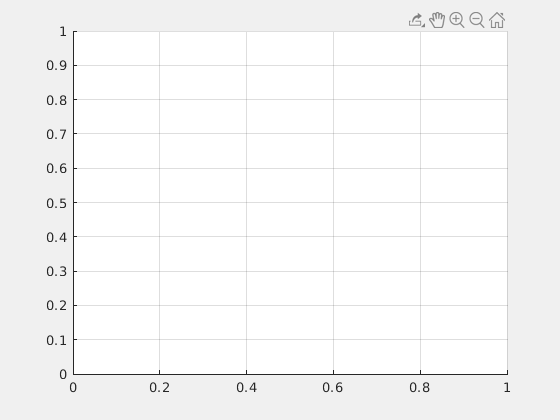

%EMAG Lab 5 -- Waveguide Properties

%Part 1 -- Ploting Dispersion Relation Beta vs f
%For a mode to exist, cut off frequency must be 
%less than operating frequency, this case 10 GHz
clear all;

f = 1E9*linspace(1, 10, 200);
operatingFrequency = 10E9;
a = 50E-3;
b = a/2;
mMax = 4;
nMax = 4;
mTE = [];
nTE = [];
mTM = [];
nTM = [];
betaTE = {};
betaTM = {};
mnOffset = 0.0;
set(gcf, 'Visible', 'on')
hold on
grid on

Legend = {};

%Generate the possible values of m and n for TE
for mCount = 0:mMax
    for nCount = 0:nMax
        tempCutOffF = cutoffFrequency(mCount, nCount, a, b);
        if tempCutOffF < operatingFrequency && ~(mCount == 0 && nCount == 0)
            mTE(end + 1) = mCount;
            nTE(end + 1) = nCount;
        end
    end
end

%Generate the possible values of m and n for TM
for mCount = 0:mMax
    for nCount = 0:nMax
        tempCutOffF = cutoffFrequency(mCount, nCount, a, b);
        if tempCutOffF < operatingFrequency && mCount ~= 0 && nCount ~= 0
            mTM(end + 1) = mCount;
            nTM(end + 1) = nCount;
        end
    end
end



%Generate beta for TE
for betaCount = 1:length(mTE)
    betaTE{betaCount} = getBeta(f, cutoffFrequency(mTE(betaCount), nTE(betaCount), a, b));     
end

%Generate beta for TM
for betaCount = 1:length(mTM)
    betaTM{betaCount} = getBeta(f, cutoffFrequency(mTM(betaCount), nTM(betaCount), a, b));       
end


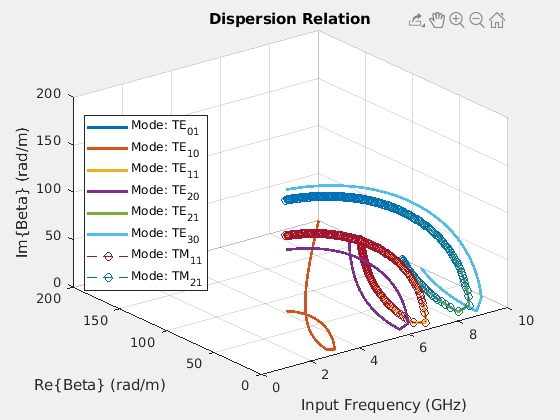

%Plotting


hold off
%subplot(2, 2, 1)
%Plot beta for TE
set(gcf, 'Visible', 'on')
for betaCount = 1:length(mTE)
    plot3(f*1E-9, real(betaTE{betaCount}), imag(betaTE{betaCount}), 'LineWidth', 2) 
    hold on
    grid on
    Legend{end + 1} = strcat('Mode: TE_{', int2str(mTE(betaCount)), int2str(nTE(betaCount)), '}' );
    %legend(Legend, 'Location', 'best')
   % w = waitforbuttonpress
end

%Plot beta for TM
%subplot(2,2,3)
for betaCount = 1:length(mTM)  
    plot3(f*1E-9, real(betaTM{betaCount}), imag(betaTM{betaCount}), '--o', 'LineWidth', 1)
    hold on
    grid on
    Legend{end + 1} = strcat('Mode: TM_{', int2str(mTM(betaCount)), int2str(nTM(betaCount)), '}' );
    %legend(Legend, 'Location', 'best')
    %w = waitforbuttonpress
end




legend(Legend, 'Location', 'best')
title('Dispersion Relation')
ylabel('Re\{Beta\} (rad/m)')
zlabel('Im\{Beta\} (rad/m)')
xlabel('Input Frequency (GHz)')